clc;
clearvars;
X1=zeros(1,39);
Y1=zeros(1,39);
%Координаты вакуумной камеры
x=[210 0 0 210 970 1680 1680 1080 210 0];
y=[0 360 3130 3490 3490 2440 1420 0 0 360];
plot(x,y,'r-');
xlim([-200,2000]);
ylim([-100,3600]);
grid on;
hold on;
axis equal;
%Периметр
P=0;
for i=1:(length(x)-2)
    P=P+sqrt((x(i)-x(i+1))^2+(y(i)-y(i+1))^2);
end
P

P = 9.0626e+03

%Количество датчиков
NumberOfSensors=39;
%Расстояние между датчиками
r=P/NumberOfSensors

r = 232.3749

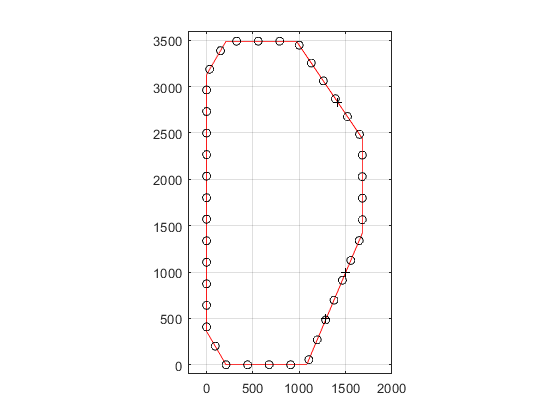

j=1;
X1(1)=x(1);
Y1(1)=y(1);
%Нахождение координат для расположения датчиков
while j<(length(x)-2)
    for i=1:(NumberOfSensors-1)
        if x(j)==x(j+1)
            [X,Y] = EquatioSolution2(x(j),r,X1(i), Y1(i));
            if (Y(1)<=Y1(i) && y(j+1)<=y(j)) || (Y(1)>=Y1(i) && y(j+1)>=y(j))
                X1(i+1)=X(1);
                Y1(i+1)=Y(1);
            else
                X1(i+1)=X(2);
                Y1(i+1)=Y(2);
            end
            [X1(i+1),Y1(i+1),j] = FunctionOverflowCheck(X1(i+1),Y1(i+1), x(j+1), x(j+2), x(j), y(j), y(j+1), y(j+2),j);
        else
            [X,Y] = EquatioSolution1(y(j),y(j+1), x(j), x(j+1),r,X1(i), Y1(i));
            if (X(1)<=X1(i) && x(j+1)<=x(j)) || (X(1)>=X1(i) && x(j+1)>=x(j))
                X1(i+1)=X(1);
                Y1(i+1)=Y(1);
            else
                X1(i+1)=X(2);
                Y1(i+1)=Y(2);
            end
            [X1(i+1),Y1(i+1),j] = FunctionOverflowCheck(X1(i+1),Y1(i+1), x(j+1), x(j+2), x(j), y(j), y(j+1), y(j+2),j);
        end
        
    end
    break;
end
plot(X1,Y1,'ko')
xlim([-200,2000]);
ylim([-100,3600]);
hold on
%Координаты патрубков
X_p=[1415, 1285, 1500];
Y_p=[2830, 495, 1000];
plot(X_p,Y_p,'k+')

%Расстояние от патрубков до начала координат для развертки (для определения расстояния от датчиков до патрубков(необходимая длина хвоста))
N_p=[5,7,7];
l=zeros(1,3);
for i=1:length(X_p)
    l(i)=sqrt((X_p(i)-x(N_p(i)))^2+(Y_p(i)-y(N_p(i)))^2);
    for j=1:(N_p(i)-1)
        l(i)=l(i)+sqrt((x(j)-x(j+1))^2+(y(j)-y(j+1))^2);
    end
end
l

l = 	1.0e+03 *

    5.1596    7.6569    7.1080


%Развертка
X_raz=zeros(2,NumberOfSensors);
for i=1:length(X_raz)
    X_raz(i)=r*(i-1);
end
RequiredTailLength=zeros(1,NumberOfSensors);
tempLength=[0,0,0,0,0,0];
for i=1:length(X_raz)
    for j=1:length(tempLength)/2
        tempLength(j)=abs(X_raz(i)-l(j));
    end
    for j=length(tempLength)/2+1:length(tempLength)
        tempLength(j)=abs(P+X_raz(i)-l(j-3));
    end
    [RequiredTailLength(1,i),RequiredTailLength(2,i)]=min(tempLength(:));
    if RequiredTailLength(2,i)>3
        RequiredTailLength(2,i)=RequiredTailLength(2,i)-3;
    end
end
RequiredTailLength

RequiredTailLength = 	1.0e+03 *

    1.4057    1.6381    1.8705    2.1029    2.3352    2.5676    2.8000    3.0324    3.2647    3.0682    2.8358    2.6034    2.3711    2.1387    1.9063    1.6739    1.4416    1.2092    0.9768    0.7444    0.5121    0.2797    0.0473    0.1851    0.4174    0.6498    0.8822    0.8339    0.6015    0.3691    0.1368    0.0956    0.2209    0.0115    0.2439    0.4762    0.7086    0.9410    1.1734
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0030    0.0030    0.0030    0.0030    0.0030    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020


Result=[X1,
    Y1,
    RequiredTailLength].';
formatSpec = '%4.0f;%4.0f;%4.0f;%1.0f\n';
fileID = fopen('Сoordinates_and_required_tail_length.txt','w');
fprintf(fileID, formatSpec, Result');
fclose(fileID);

function [X,Y] = EquatioSolution1(yj,yj_1, xj, xj_1,r,X1i, Y1i)
    k=(yj-yj_1)/(xj-xj_1);
    m=yj-k*xj;
    syms X Y;
    [X,Y]=solve(k*X+m-Y,(X-X1i)^2+(Y-Y1i)^2-r^2);
    X(1)=double(X(1));
    Y(1)=double(Y(1));
    X(2)=double(X(2));
    Y(2)=double(Y(2));    
end

function [X,Y] = EquatioSolution2(xj,r,X1i, Y1i)
    syms X Y;
    [X,Y]=solve(X-xj,(X-X1i)^2+(Y-Y1i)^2-r^2);
    X(1)=double(X(1));
    Y(1)=double(Y(1));
    X(2)=double(X(2));
    Y(2)=double(Y(2));    
end

function [X1i_1,Y1i_1,j] = FunctionOverflowCheck(X1i_1,Y1i_1, xj_1, xj_2, xj, yj, yj_1,yj_2,j)
        % Проверка находится ли какая-либо из координат вне границ отрезка
    if (X1i_1>xj_1 && X1i_1>xj) || (X1i_1<xj_1 && X1i_1<xj) || (Y1i_1<yj_1 && Y1i_1<yj) || (Y1i_1>yj_1 && Y1i_1>yj)
        x_1=X1i_1-xj_1;
        y_1=Y1i_1-yj_1;
        r1=sqrt(x_1^2+y_1^2);
        if xj_1==xj_2
            [X,Y] = EquatioSolution2(xj_1,r1,xj_1, yj_1);
            if (Y(1)>=yj_1 && Y(1)<=yj_2) || (Y(1)<=yj_1 && Y(1)>=yj_2)
                X1i_1=X(1);
                Y1i_1=Y(1);
            else
                X1i_1=X(2);
                Y1i_1=Y(2);
            end
        else
            [X,Y] = EquatioSolution1(yj_1,yj_2, xj_1, xj_2,r1,xj_1, yj_1);
            if ((X(1)>=xj_1 && X(1)<=xj_2)) || ((X(1)<=xj_1 && X(1)>=xj_2))
                X1i_1=X(1);
                Y1i_1=Y(1);
            else
                X1i_1=X(2);
                Y1i_1=Y(2);
            end
        end
        j=j+1;
    end    
end


